## ME319 Prelab 6 Digital Filtering - Offline

`In this prelab we will review the process of analyzing a noisy signal, designing digital filters and implementing them as difference equations.`

`Let's first create a noisy signal by combining  sinusoidal signals of different amplitudes and frequencies, and adding random noise to it.`

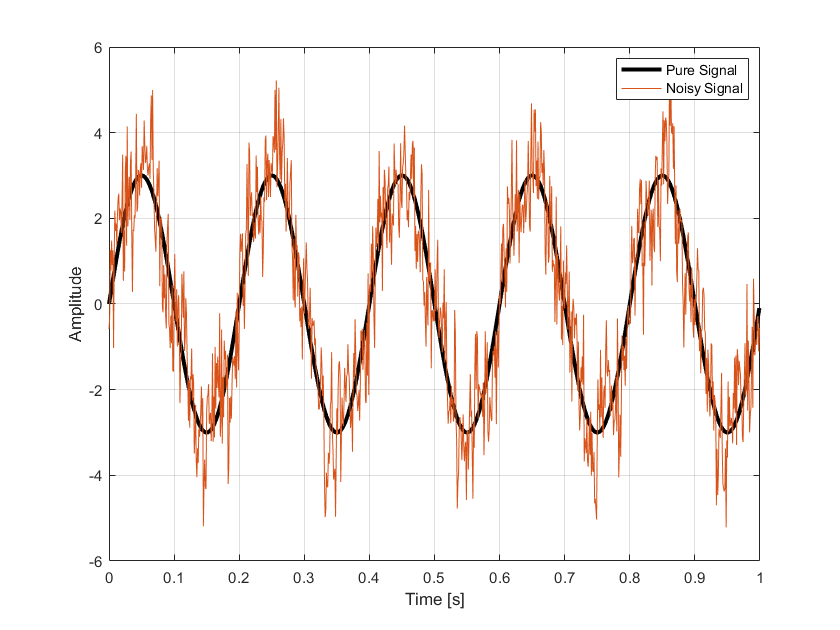

clear all;
Fs = 1000;
T = 1 / Fs;
L = 1000;
t = (0:L-1)*T;
A = 3;
f1 = 5; % Hz - Base frequency
% Base Signal
OriginalData = A * sin(2*pi* f1 * t);


% Add Higher Frequency Components
NoisyData1 = OriginalData + 0.2*A*sin(2*pi*f1*4*t) +  0.2*A*sin(2*pi*f1*16*t);
% Add random noise
NoisyData = NoisyData1 + 0.25*A*randn(1, length(t));


figure()
plot(t,OriginalData, 'LineWidth',3, 'color', 'k'); xlabel('Time [s]'); ylabel('Amplitude'); grid on; hold on;
plot(t,NoisyData); 
legend('Pure Signal', 'Noisy Signal')
hold off;

Let's decompose the signal and look at its frequency spectrum by using an FFT (Fast Fourier Transform). We want to observe the strength of the of each frequency component

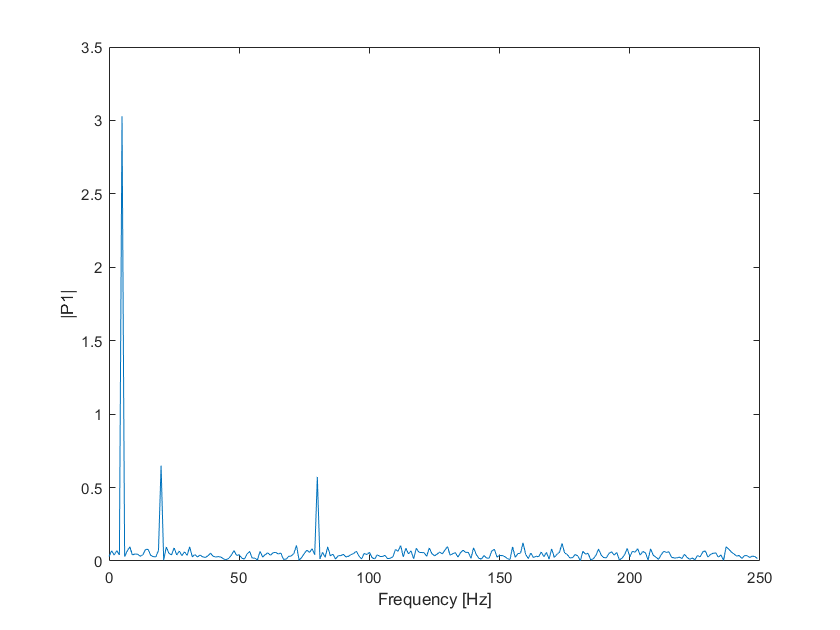

y = fft(NoisyData);
L = length(t);
P2 = abs(y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2 * P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f(1:end/2),P1(1:end/2)); xlabel('Frequency [Hz]'); ylabel('|P1|');

We can see that we have three main frequency components, as expected, the other ripple is due to the random noise we added. Let's apply a first order filter first and see if we can remove the noise and higher frequency components. 

## Simple First Order Filter 

A simple first order low pass filter takes the Laplace form


$$F\left(s\right)=\frac{1}{1+s\omega_{c\;} }$$


And in the discrete Z-domain


$$F\left(z^{-1} \right)=\frac{\left(1-\alpha \right)z^{-1} }{1-\alpha \;z^{-1} }$$


It is implemented in a digital form as a difference equation


$$y\left\lbrack k\right\rbrack =\left(1-\alpha \;\right)x\left\lbrack k-1\right\rbrack +\alpha \;y\left\lbrack k-1\right\rbrack$$


where $\alpha =e^{-2\pi \;{\omega \;}_{c\;} T_{s\;} }$

## Bode Plots

Bode plots are a useful tool for assessing the performance of a signal filter. They are composed of a magnitude and phase diagram. The magnitude diagram gives us the magnitude ratio (gain) between the output and input of the filter at a range of frequencies. While the phase diagram gives us the phase shift of the output signal compared to the input signal.

We can convert our filter parameters into transfer functions using the TransferFunction command from scipy.signal, then call the bode function from within the transfer function object.

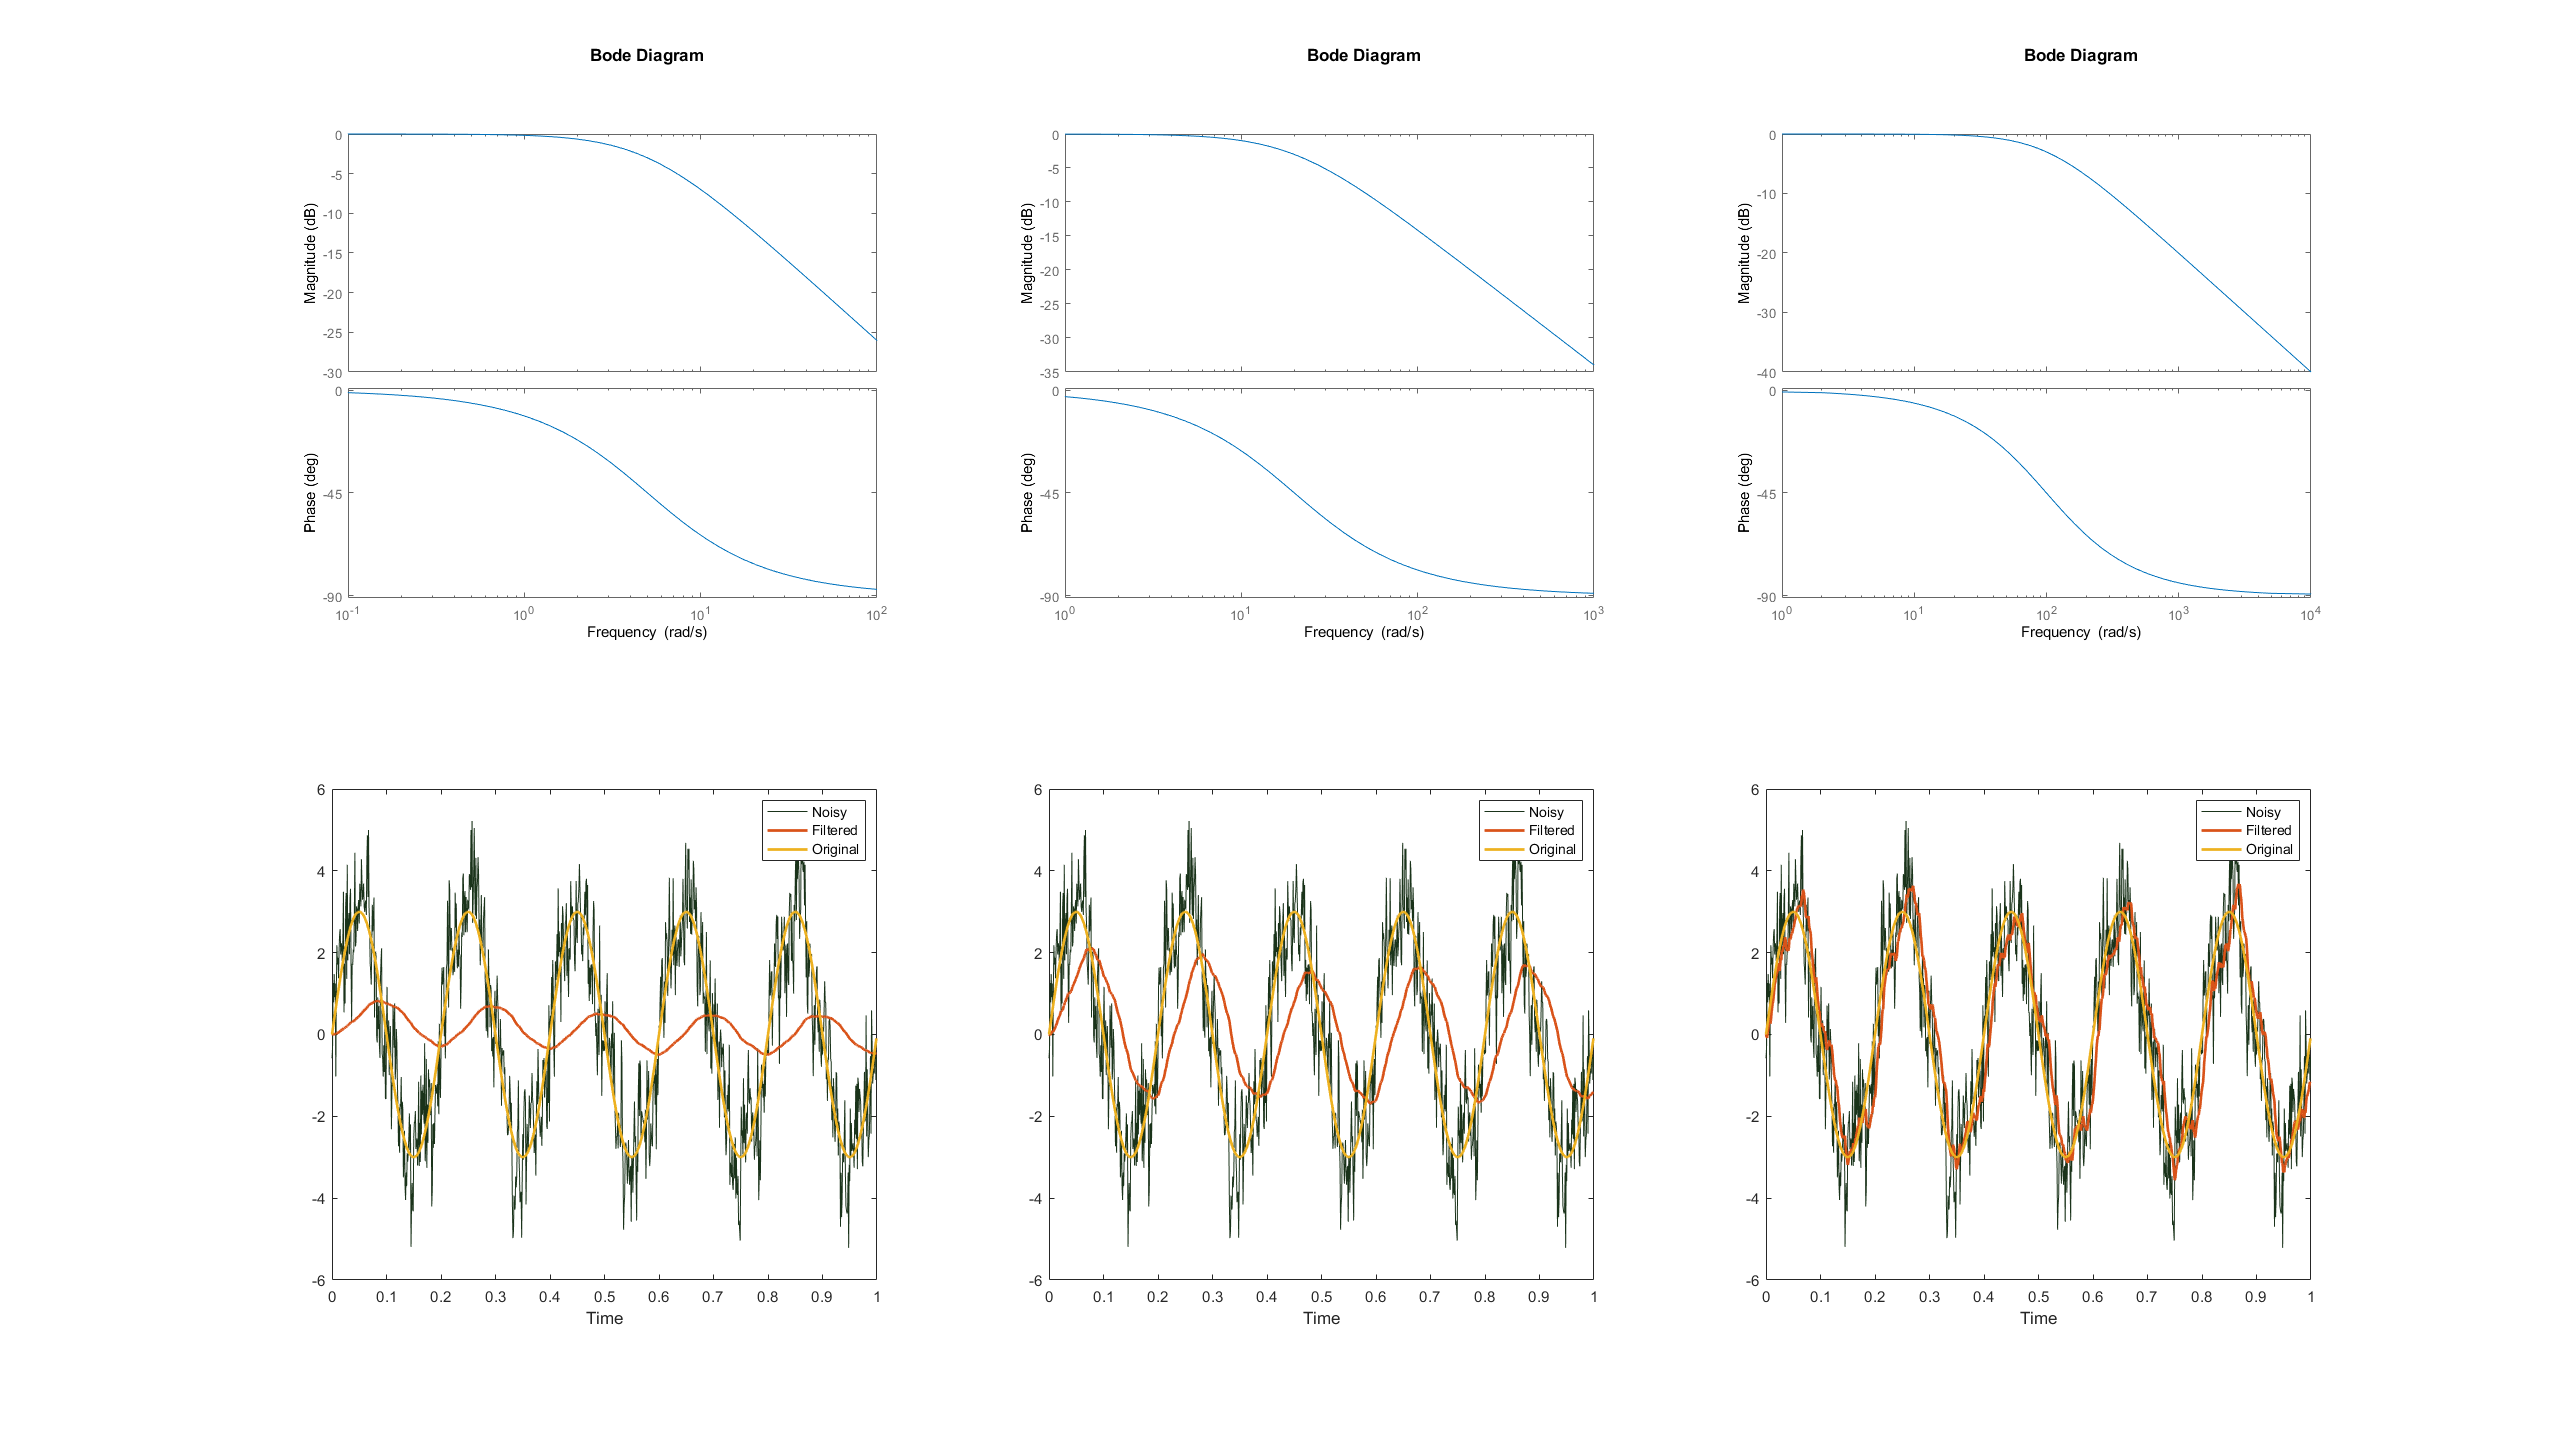

Hz =
 
  0.004988
  ---------
  z - 0.995
 
Sample time: 0.001 seconds
Discrete-time transfer function.



a =          0    0.0050


b =     1.0000   -0.9950


Hz =
 
    0.0198
  ----------
  z - 0.9802
 
Sample time: 0.001 seconds
Discrete-time transfer function.



a =          0    0.0198


b =     1.0000   -0.9802


Hz =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 0.001 seconds
Discrete-time transfer function.



a =          0    0.0952


b =     1.0000   -0.9048


s = tf('s');
wc = [5, 20, 100];
l= length(wc);
fig = figure();
fig.Position = [500 400 1920 1080]; 

for k=1:l
    % Construct the first order continous filter
    H = 1 / (s/wc(k) + 1);
    % Convert to discrete
    Hz = c2d(H,T)
    % Grab the num / den coefficients of the discrete T.F.
    [num,den] = tfdata(Hz, 'v');
    a = num
    b = den
    FilteredData1stOrder = zeros(1,length(OriginalData));

    for m = 2:length(NoisyData)
        FilteredData1stOrder(m) = - b(2) * FilteredData1stOrder(m-1) + a(2) * NoisyData(m-1);
    end
    %Compute the mean square error between the original signal and the filtered signal
    LpError(k) = immse(OriginalData,FilteredData1stOrder); 
    
    %BLOTTING
    subplot(2,3,k)
    % We'll also plot the Bode diagram of the continous filter
    bode(H)
    subplot(2,3,k+3)
    plot(t,NoisyData, 'Color', [.1 .2 .1], 'LineWidth', 0.5); hold on;
    plot(t,FilteredData1stOrder, 'LineWidth', 2);
    plot(t,OriginalData, 'LineWidth', 2);
    hold off; 
    legend('Noisy', 'Filtered', 'Original');
    xlabel('Time');
end

LpError

LpError =     4.3660    3.1753    0.5742


## Butterworth Filter

Now let's try to apply a butterworth filter instead.

[Butterworth_filter](https://en.wikipedia.org/wiki/Butterworth_filter)

"The Butterworth filter is a type of signal processing filter designed to have a frequency response as flat as possible in the passband" 

In other words, the Butterworth filter will attempt to retain more of the signal strength (amplitude) in the frequency region desired. Here we chose to use a 2nd order Butterworth filter. It's transfer function in the z-domain is


$$F\left(z^{-1} \right)=\frac{b_2 +b_1 z^{-1} b_0 z^{-2} }{1-a_1 z^{-1} -a_2 z^{-2} }$$


which gives the difference equation


$$y\left\lbrack k\right\rbrack =b_2 x\left\lbrack k\right\rbrack +b_1 x\left\lbrack k-1\right\rbrack +b_0 x\left\lbrack k-2\right\rbrack -a_1 y\left\lbrack k-1\right\rbrack -a_2 y\left\lbrack k-2\right\rbrack$$


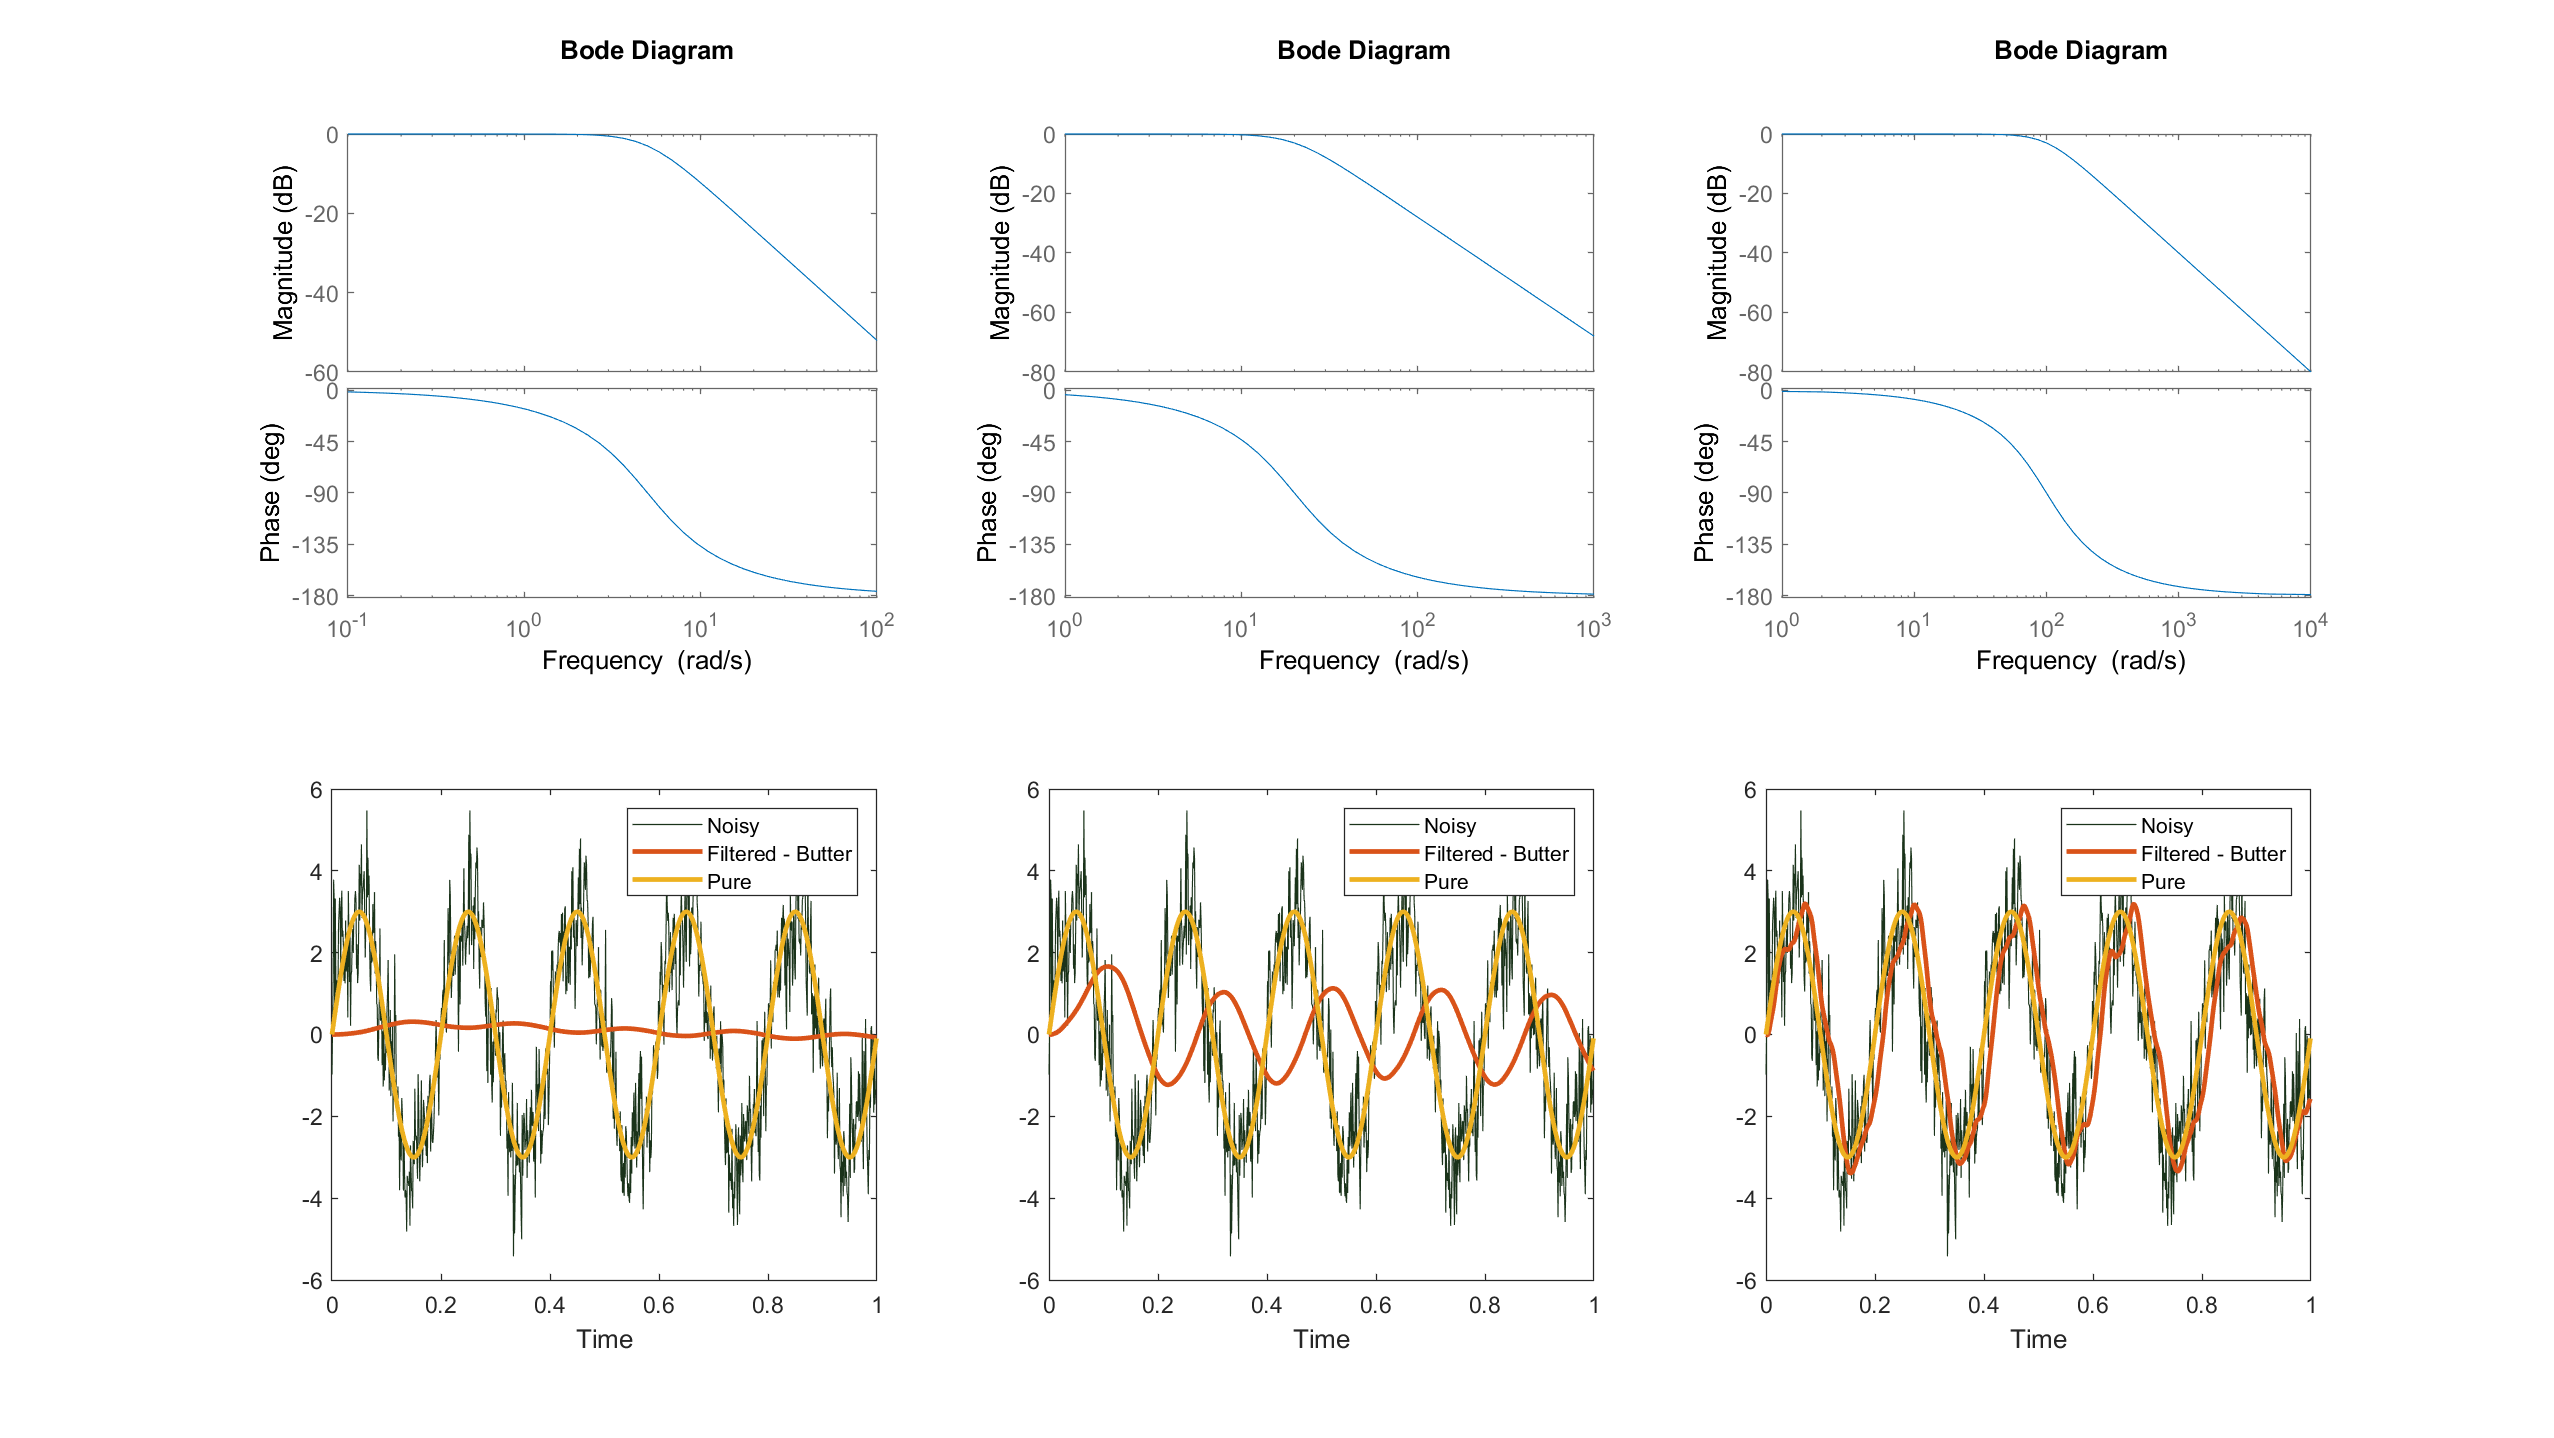

Hz =
 


Hz =
 
  0.0001981 z + 0.0001963
  -----------------------
  z^2 - 1.972 z + 0.9721
 
Sample time: 0.001 seconds
Discrete-time transfer function.



Hz =
 
  0.004768 z + 0.004549
  ----------------------
  z^2 - 1.859 z + 0.8681
 
Sample time: 0.001 seconds
Discrete-time transfer function.



wc = [5, 20, 100]; %Hz
l= length(wc);
fig = figure();
fig.Position = [500 400 1920 1080];

for k=1:l
    % The built-in butter function from the signal processing toolbox is
    % used
    [numS,denS] = butter(2, wc(k), 'low', 's');
    % Construct the continous T.F
    H = tf(numS,denS);
    Hz = c2d(H,T)
    [num,den] = tfdata(Hz, 'v');
    
    % Apply the filter() - the filter function applies the difference
    % equation on the supplied data
    FilteredDataButter = filter(num, den, NoisyData);
    ButterError(k) = immse(OriginalData,FilteredDataButter);
    
    %BLOTTING
    subplot(2,3,k)
    bode(H)
    subplot(2,3,k+3)
    plot(t,NoisyData, 'Color', [.1 .2 .1], 'LineWidth', 0.5); hold on;
    plot(t,FilteredDataButter, 'LineWidth', 2);
    plot(t,OriginalData, 'LineWidth', 2);
    hold off; 
    legend('Noisy', 'Filtered - Butter', 'Pure');
    xlabel('Time');
end

ButterError

The butterworth filter doesn't improve the phase delay much. Let's try a bessel filter 

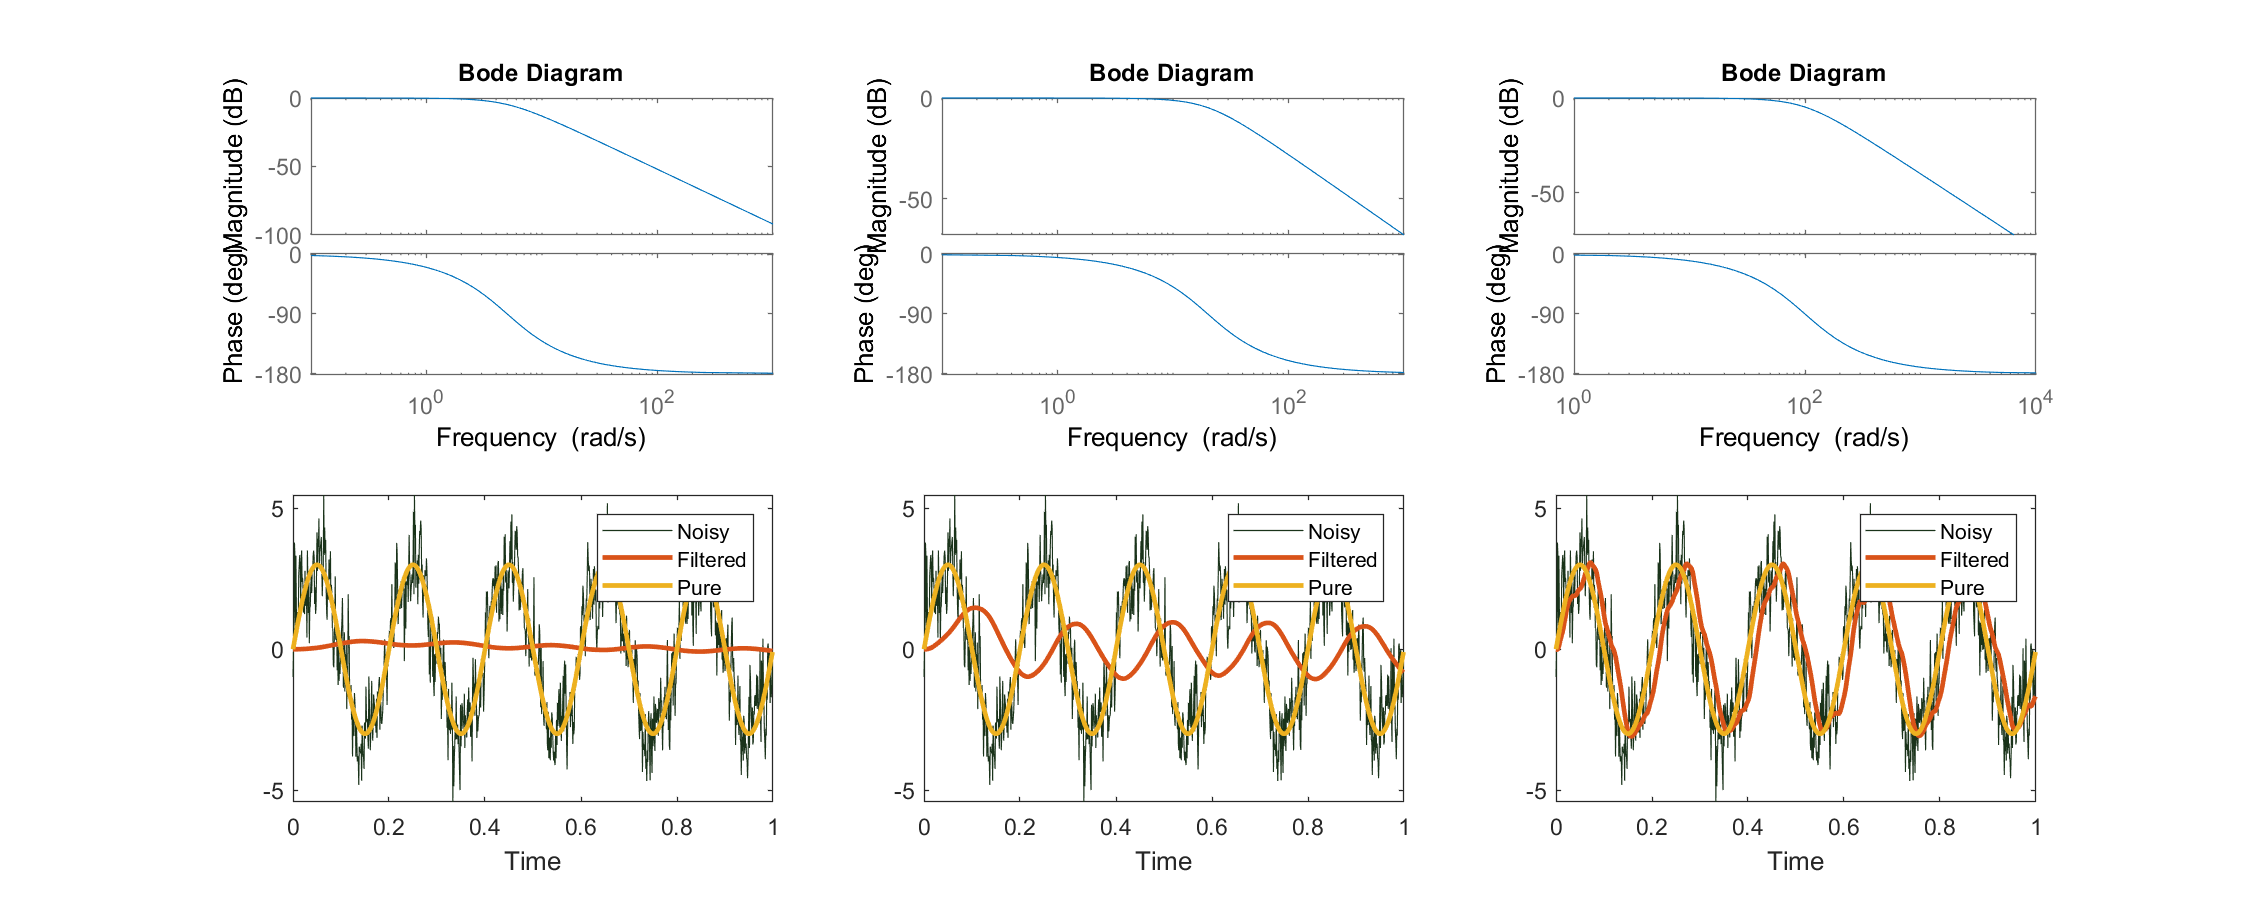

wc = [5, 20, 100]; %Hz
l= length(wc);
fig = figure();
fig.Position = [573 438 1500 600];

for k=1:l
    [numS,denS] = besself(2, wc(k));
    H = tf(numS,denS);
    Hz = c2d(H,T);
    [num,den] = tfdata(Hz, 'v');
    FilteredDataBessel = filter(num, den, NoisyData);
    BesselError(k) = immse(OriginalData,FilteredDataBessel);
    %BLOTTING
    subplot(2,3,k)
    bode(H)
    subplot(2,3,k+3)
    plot(t,NoisyData, 'Color', [.1 .2 .1], 'LineWidth', 0.5); hold on;
    plot(t,FilteredDataBessel, 'LineWidth', 2);
    plot(t,OriginalData, 'LineWidth', 2);
    hold off; 
    legend( 'Noisy', 'Filtered', 'Pure');
    xlabel('Time');
end

We can see that a cut-off frequency of 100Hz is required to maintain a decent amplitude response. A a first order low pass filter produces the best phase reponse, and worst filtering. So it is a trade-off between good filtering vs. maintaining phase response. 

Let's try to apply a first order low pass filter to maintain a good phase response, but then add two notch filters to attack the higher frequency visible components at f = 4*5Hz, 16*5Hz

s = tf('s');
wclp = 75; %Hz
fig = figure();
fig.Position = [573 438 1500 600];
Hlp = 1 / (s/wclp + 1);
Hzlp = c2d(Hlp,T);
[numN1, denN1] = iirnotch(4*f1/(3.15*Fs), 4*f1/(3.15*Fs)/35);
HzN1 = tf(numN1,denN1, T);

[numN2, denN2] = iirnotch(16*f1/(3.15*Fs), 16*f1/(3.15*Fs)/35);
HzN2 = tf(numN2,denN2, T);

HzF = Hzlp * HzN1 * HzN2

HzF =
 
                                        
  0.07215 z^4 - 0.2881 z^3 + 0.4319 z^2 
                                        
                    - 0.2881 z + 0.07215
                                        
  ---------------------------------------
                                         
  z^5 - 4.918 z^4 + 9.68 z^3 - 9.531 z^2 
                                         
                      + 4.694 z - 0.9251 
                                         
 
Sample time: 0.001 seconds
Discrete-time transfer function.



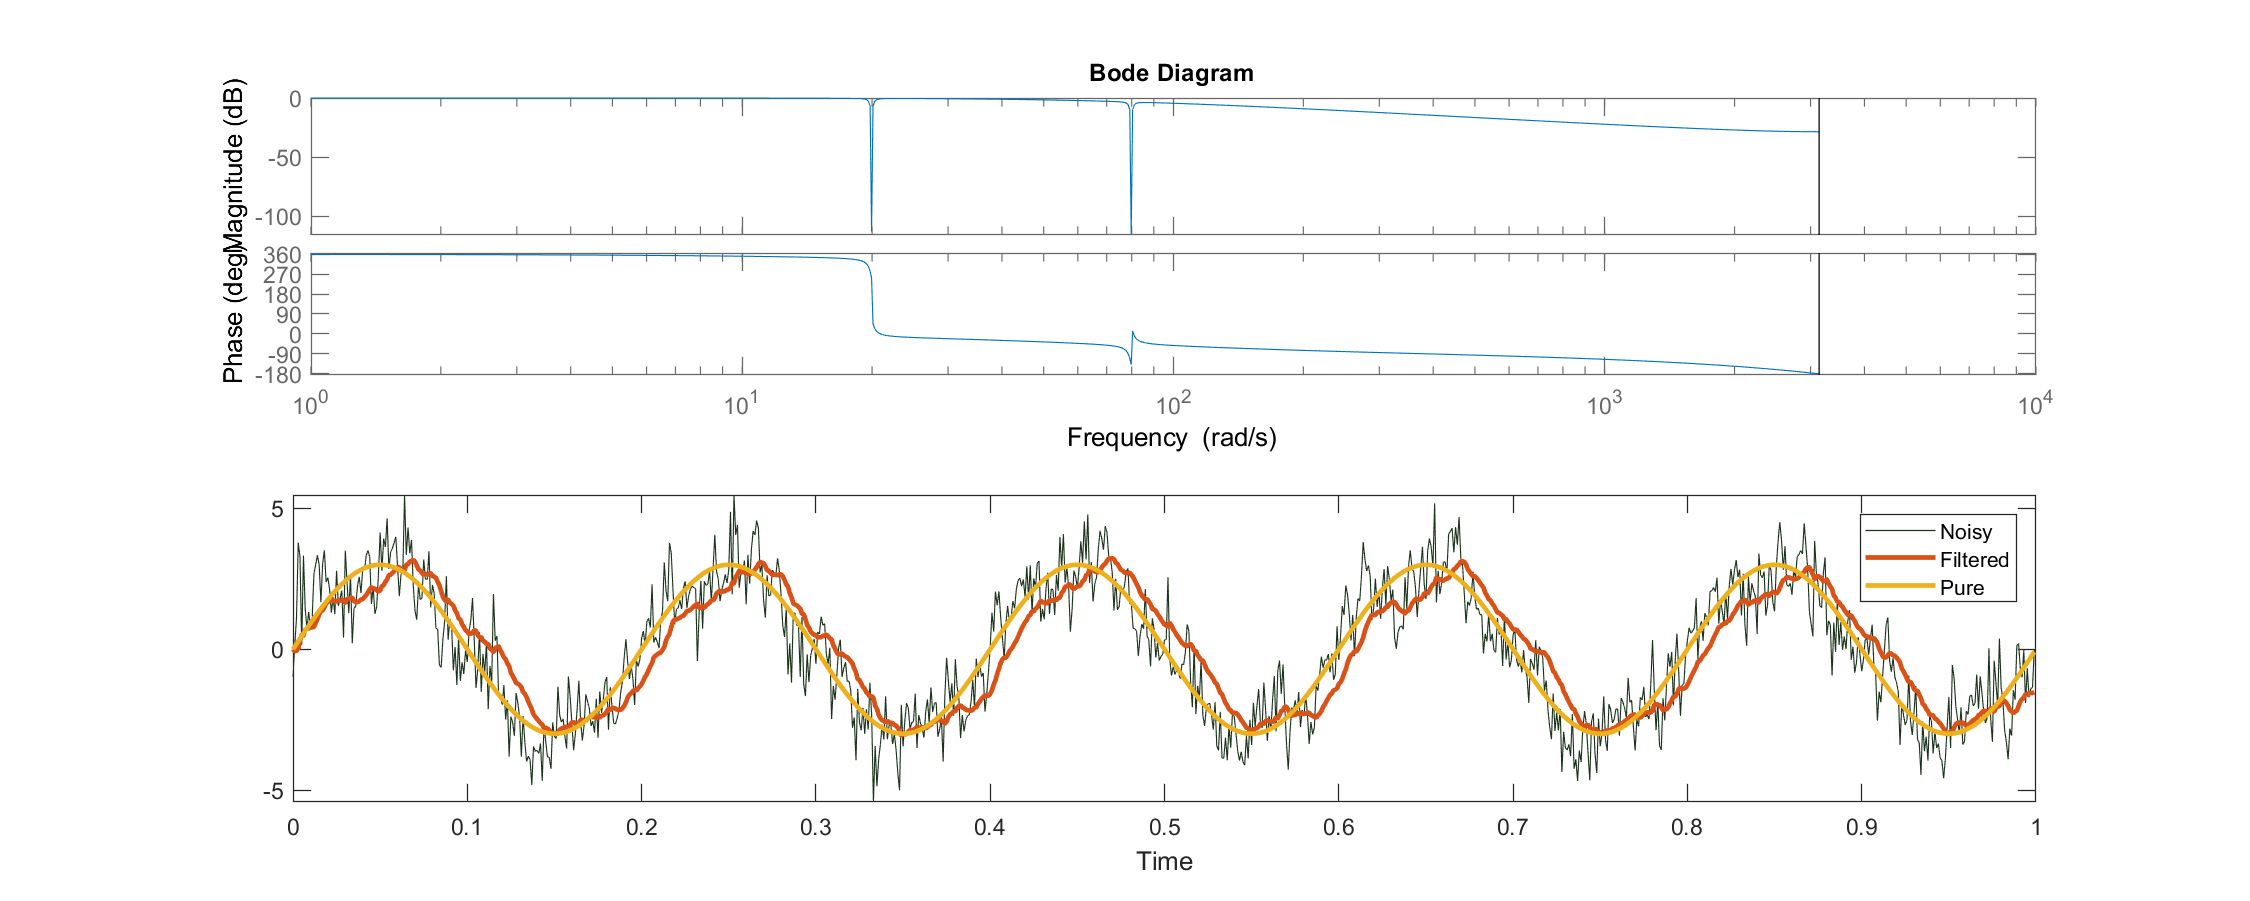

[num,den] = tfdata(HzF, 'v');
FilteredDataNotch = filter(num, den, NoisyData);
LpNotchError = immse(OriginalData,FilteredDataNotch);
subplot(2,1,1)
bode(HzF)
subplot(2,1,2)
plot(t,NoisyData, 'Color', [.1 .2 .1], 'LineWidth', 0.5); hold on;
plot(t,FilteredDataNotch, 'LineWidth', 2);
plot(t,OriginalData, 'LineWidth', 2);
hold off; 
legend('Noisy', 'Filtered', 'Pure' );
xlabel('Time');

Let's compare the root-mean-square error for each of the different methods tried.

display(LpError)

LpError =     4.3660    3.1753    0.5742


ButterError

ButterError =     4.5531    4.0381    4.4491


BesselError

BesselError =     4.7395    6.2408    1.3657


LpNotchError

LpNotchError = 0.7413

The improvement gained by the notch filter here is minimal. A first order low-pass filter is a simple method to use. Designing higher order special filters requires careful considerations. 

These are just a few of the basic methods of filtering signals. A more involved design can be achieve which produces an optimal estimator like a Kalman Filter where a model of the measured system dynamics and the stochastic properties of the sensor and process are included in the design. This is outside the scope of this course. 